%%This script will implement OTFS for Radar Modeling as well as
%%Communication modeling


## Radar Modeling

%%Define Parameters  
M = 64;         
N = 30; 
fc = 5e9; 
df = 15e3; 

SNR = 10; 

pLen = 10;    
padding = 'ZP'; 

NullBin = floor(N/2)+1;
Nulldd = zeros(M,N);
Nulldd(1,NullBin) = exp(1i*pi/4); 

%%Simmulate OTFS Modulation
txOut = OTFSModulator(Nulldd,pLen,padding);


%%Define The Channel
chanParams.pathDelays      = [0  5  7 10]; 
chanParams.pathGains       = [1  0.6 0.4  0.3]; 
chanParams.pathDopplers    = [0 3   -5   -8]; 

fsamp = M*df;                
if strcmp(padding,'ZP') || strcmp(padding,'CP')
    Meff = M + pLen;      
    numSamps = Meff * N;     
    T = ((M+pLen)/(M*df)); 
else
    Meff = M;                
    numSamps = M*N + pLen; 
    T = 1/df;                
end

%%Get Frequency in Proper Units
chanParams.pathDopplerFreqs = chanParams.pathDopplers * 1/(N*T); 


dopplerOut = dopplerChannel(txOut,fsamp,chanParams);

Es = mean(abs(pskmod(0:3,4,pi/4).^ 2));
n0 = Es/(10^(SNR/10));
chOut = awgn(dopplerOut,SNR,'measured');

%%Output the Values For Each Path
for k = 1:length(chanParams.pathDelays)
    fprintf('Path %d\n',k);
    fprintf('\tDelay = %5.2f us\n', 1e6*chanParams.pathDelays(k)/(Meff*df));
    fprintf('\tRelative Doppler shift = %5.0f Hz (%5.0f km/h)\n', ...
        chanParams.pathDopplerFreqs(k), (physconst('LightSpeed')*chanParams.pathDopplerFreqs(k)/fc)*(3600/1000));
    fprintf('\tRange = %5.2f m', physconst('LightSpeed')*chanParams.pathDelays(k)/(Meff*df))
end

Path 1


	Delay =  0.00 us


	Relative Doppler shift =     0 Hz (    0 km/h)


	Range =  0.00 m

Path 2


	Delay =  4.50 us


	Relative Doppler shift =  1297 Hz (  280 km/h)


	Range = 1350.42 m

Path 3


	Delay =  6.31 us


	Relative Doppler shift = -2162 Hz ( -467 km/h)


	Range = 1890.58 m

Path 4


	Delay =  9.01 us


	Relative Doppler shift = -3459 Hz ( -747 km/h)


	Range = 2700.83 m

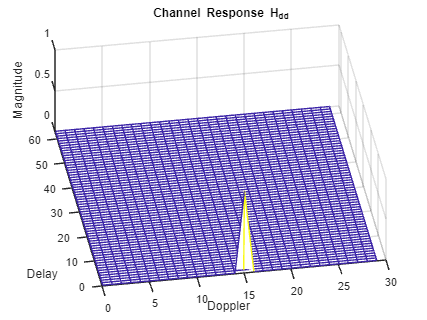



recieverSent = chOut(1:numSamps);

% OTFS demodulation
Ydd = OTFSDemodulator(recieverSent,M,pLen,0,padding);

%%Compute the Transfer Frame
Hdd = Ydd * conj(Nulldd(1,NullBin)) / (abs(Nulldd(1,NullBin))^2 + n0);


%%Plot Output
figure;
xa = 0:1:N-1;
ya = 0:1:M-1;
mesh(xa,ya,abs(Nulldd));
view([-9.441 62.412]);
title('Channel Response H_{dd}');
zlabel('Magnitude');
xlabel('Doppler');
ylabel('Delay');

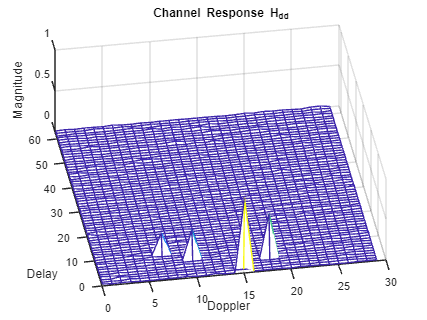



%%Plot the Transfer Function
figure;
xa = 0:1:N-1;
ya = 0:1:M-1;
mesh(xa,ya,abs(Hdd));
view([-9.441 62.412]);
title('Channel Response H_{dd}');
zlabel('Magnitude');
xlabel('Doppler');
ylabel('Delay');




%Channel Estimation
[lp,vp] = find(abs(Hdd) >= 0.05);
chanEst.pathGains = diag(Hdd(lp,vp));   
chanEst.pathDelays = lp - 1;           
chanEst.pathDopplers = vp - NullBin;   
chanEst.pathDopplerFreqs = chanEst.pathDopplers * 1/(N*T); 

%%Output the Paths and their values (as before)
for k = 1:length(chanEst.pathDelays)
    fprintf('Path %d\n',k);
    fprintf('\tDelay=%5.2fus\n', 1e6*chanEst.pathDelays(k)/(Meff*df));
    fprintf('\tRelative Doppler shift=%5.0fHz (%5.0fkm/h)\n', ...
        chanEst.pathDopplerFreqs(k), (physconst('LightSpeed')*chanEst.pathDopplerFreqs(k)/fc)*(3600/1000));
    fprintf('\tRange = %5.2f m', physconst('LightSpeed')*chanEst.pathDelays(k)/(Meff*df))
end

Path 1


	Delay= 9.01us


	Relative Doppler shift=-3459Hz ( -747km/h)


	Range = 2700.83 m

Path 2


	Delay= 6.31us


	Relative Doppler shift=-2162Hz ( -467km/h)


	Range = 1890.58 m

Path 3


	Delay= 0.00us


	Relative Doppler shift=    0Hz (    0km/h)


	Range =  0.00 m

Path 4


	Delay= 4.50us


	Relative Doppler shift= 1297Hz (  280km/h)


	Range = 1350.42 m

## OTFS COMM MODELING

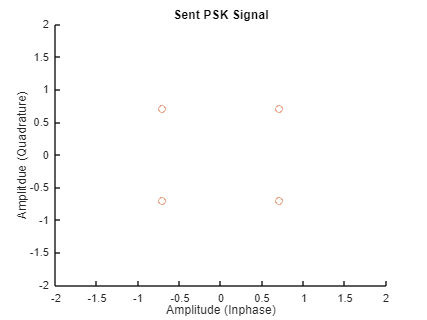



% Generate our Data
Xgrid = zeros(M,N);
Xdata = randi([0,1],2*M,N);
Xgrid(1:M,:) = pskmod(Xdata,4,pi/4,InputType="bit");

% OTFS modulation
txOut = OTFSModulator(Xgrid,pLen,padding);

% Add channel and noise
dopplerOut = dopplerChannel(txOut,fsamp,chanParams);
chOut = awgn(dopplerOut,SNR,'measured');

G = getG(M,N,chanEst,pLen,padding);

rxWindow = chOut(1:numSamps);
y_otfs = ((G'*G)+n0*eye(Meff*N)) \ (G'*rxWindow); 

%Demodulate
Xhat_otfs = OTFSDemodulator(y_otfs,M,pLen,0,padding);


%%SEnt Symbols
figure;
scatter(real(Xgrid),imag(Xgrid));
xlim([-2 2]);
ylim([-2 2]);
title("Sent PSK Signal");
xlabel("Amplitude (Inphase)");
ylabel("Amplitdue (Quadrature)");

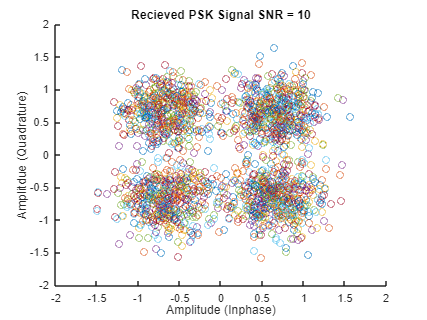



%% Plot the Recieved Bits
figure;
scatter(real(Xhat_otfs),imag(Xhat_otfs));
xlim([-2 2]);
ylim([-2 2]);
title("Recieved PSK Signal SNR = 10");
xlabel("Amplitude (Inphase)");
ylabel("Amplitdue (Quadrature)");



XhatData = pskdemod(Xhat_otfs,4,pi/4,OutputType="bit",OutputDataType="logical");
[~,ber] = biterr(Xdata,XhatData);
fprintf('OTFS BER = %3.3e\n', ber);  

OTFS BER = 1.094e-02
